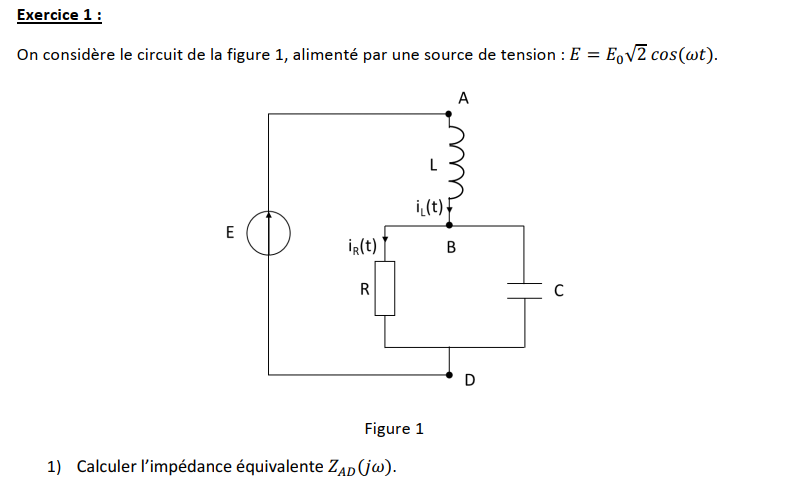

syms R L C w positive
ZAD=i*L*w+R/(1+R*C*i*w)

$$ZAD = L\,w\,\mathrm{i}+\frac{R}{1+C\,R\,w\,\mathrm{i}}$$

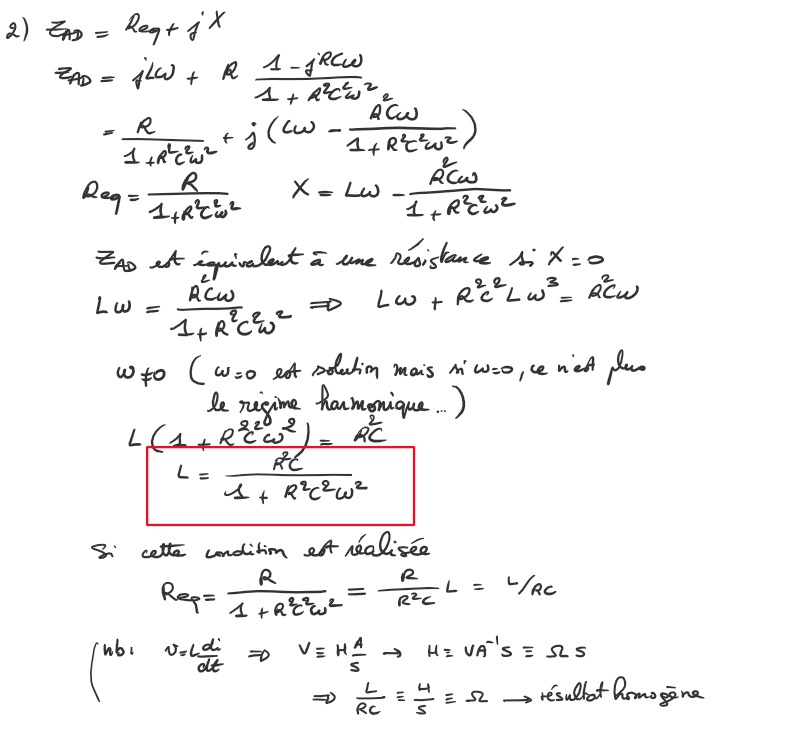

Req=real(ZAD)

$$Req = \frac{R}{C^{2}\,R^{2}\,w^{2}+1}$$

X=imag(ZAD)

$$X = L\,w-\frac{C\,R^{2}\,w}{C^{2}\,R^{2}\,w^{2}+1}$$

solve(X,L)  % valeur de L qui annule X

$$ans = \frac{C\,R^{2}}{C^{2}\,R^{2}\,w^{2}+1}$$

simplify(subs(Req,w,solve(X,w))) % Req avec X=0, expression de Req sans w

$$ans = \frac{L}{C\,R}$$

L=solve(X,L)

$$L = \frac{C\,R^{2}}{C^{2}\,R^{2}\,w^{2}+1}$$

R=100;C=100/3*1e-6;w=400;
double(subs(L))

ans = 0.1200

Pour $R=100\ \rm \Omega$ $C=100/3\ \rm µF$ et $\omega=400\ \rm rd/s$, $L=0.12\ \rm H$ annule la partie imaginaire de $Z_{AD}$.

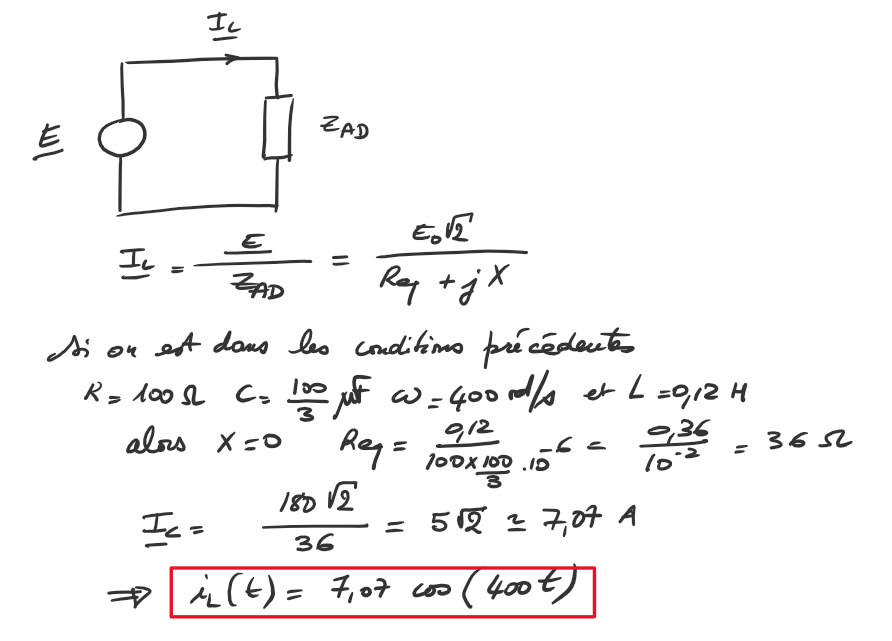

L=0.12

L = 0.1200

IL=180*2^.5/subs(ZAD) % amplitude complexe associée à i_L(t)

$$IL = 5\,\sqrt{2}$$

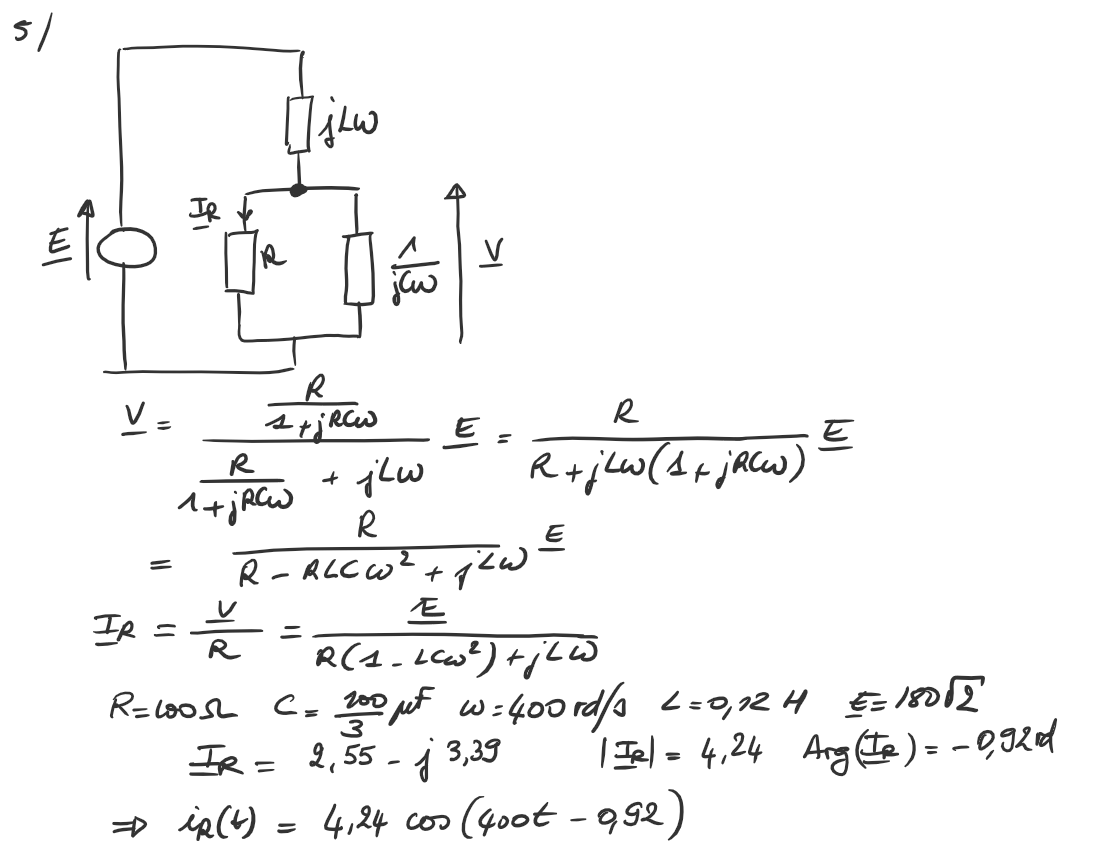

On mène le calcul sur le circuit équivalent comme en continu, avec les impédances complexes équivalentes à des resistances. On peut de ce fait utiliser fspice pour calculer $\underline{I_R}$:

netlist={
    'V1 A 0 180*2^.5'
    'RA A B i*.12*400'
    'RB B 0 100'
    'RC B 0 1/(100/3*1e-6)/i/400'
    };
[X name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} 254.55844122715710878430397035775\\ 254.55844122715710878430397035775-339.41125496954281171240529381033\,\mathrm{i}\\ -7.0710678118654752440084436210485-4.4081038155835781548827620145834e-39\,\mathrm{i} \end{array}\right)$$

name = 1×3 cell array
    {'V(A)'}    {'V(B)'}    {'I(V1)'}


IR=X(2)/100

$$IR = 2.5455844122715710878430397035775-3.3941125496954281171240529381033\,\mathrm{i}$$

Par définition la puissance consommée par la résistance est la moyenne de la puissance instantanée $P=\frac{1}{T} \int_{(T)}{p(t)dt}$ avec $p(t)=u_R(t)\times i_R(t)=Ri_R^2(t)$


$$i_R(t)=I_Rcos(\omega t+\varphi) \\\Longrightarrow P=\frac{1}{T}\int_{(T)}{RI_R^2cos^2(\omega t+\varphi)dt}=R\left(\frac{I_R}{\sqrt{2}} \right)^2={RI_{R_{eff}}^2$$


Application numérique :

$i_R(t)=4.24cos(400t-0.92)$, d'où $P=100\left({\frac{4.24}{\sqrt{2}}}\right)^2=898.9\ \rm W$

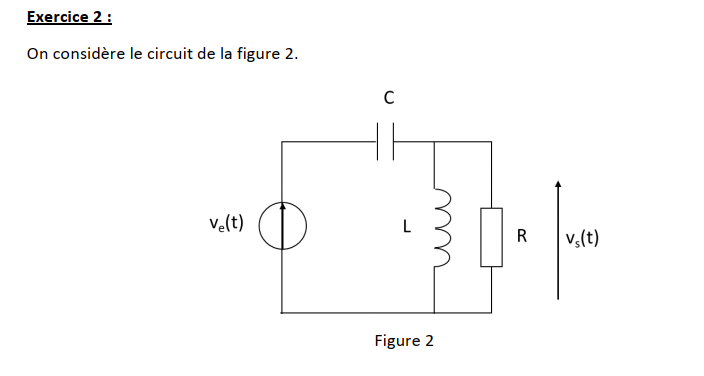

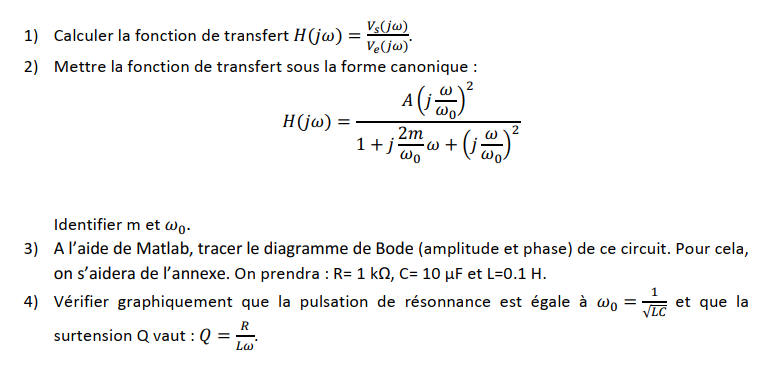

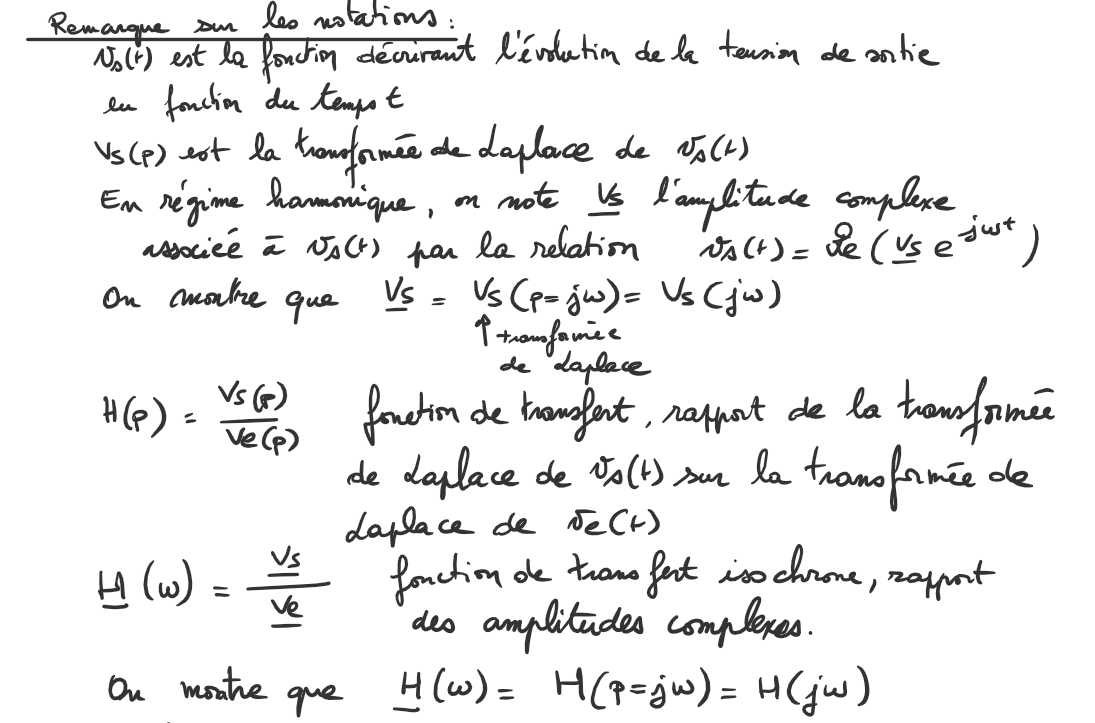

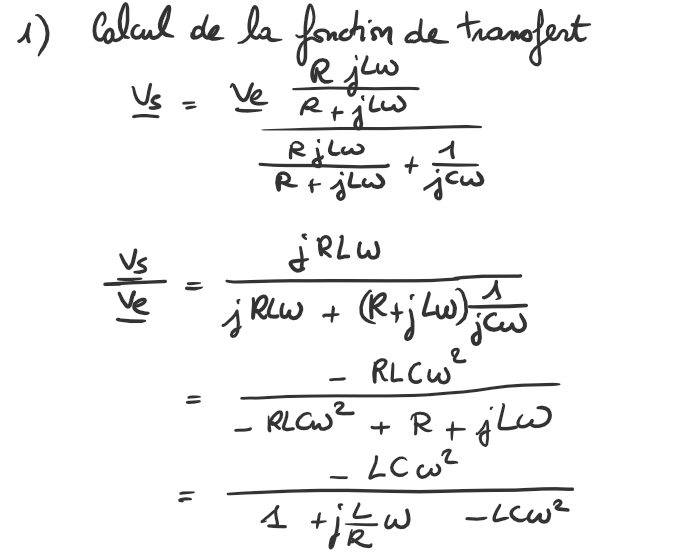

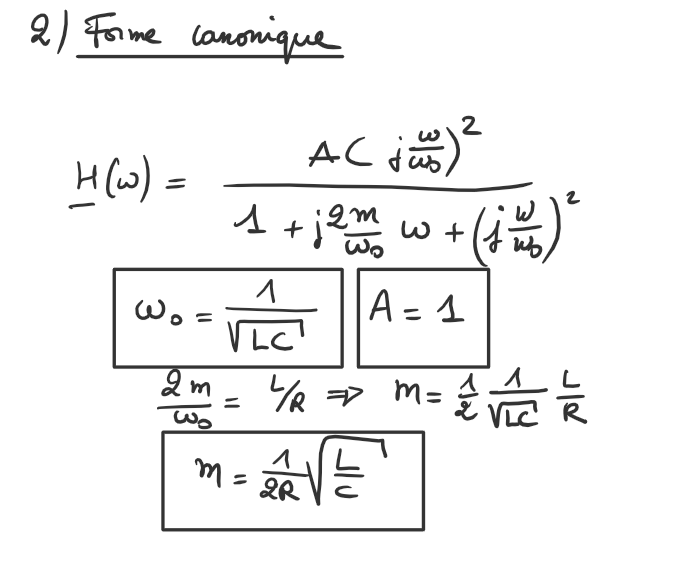

Utilisation de fspice pour obtenir ce résultat :

La netlist correspond au schéma équivalent complexe, où chaque impédance est traitée comme un résistance en continu.

netlist={
    'Ve 1 0 ve'
    'R1 1 2 1/C/1i/w'
    'R2 2 0 R'
    'R3 2 0 1i*L*w'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} \mathrm{ve}\\ -\frac{C\,L\,R\,\mathrm{ve}\,w^{2}}{-C\,L\,R\,w^{2}+\mathrm{i}\,L\,w+R}\\ -\frac{C\,\mathrm{ve}\,w\,\left(R+L\,w\,\mathrm{i}\right)\,\mathrm{i}}{-C\,L\,R\,w^{2}+\mathrm{i}\,L\,w+R} \end{array}\right)$$

name = 1×3 cell array
    {'V(1)'}    {'V(2)'}    {'I(Ve)'}


La fonction de transfert est X(2)/X(1) :

H=X(2)/X(1)

$$H = -\frac{C\,L\,R\,w^{2}}{-C\,L\,R\,w^{2}+\mathrm{i}\,L\,w+R}$$

On retrouve le résultat précedent avant mise sous forme canonique.

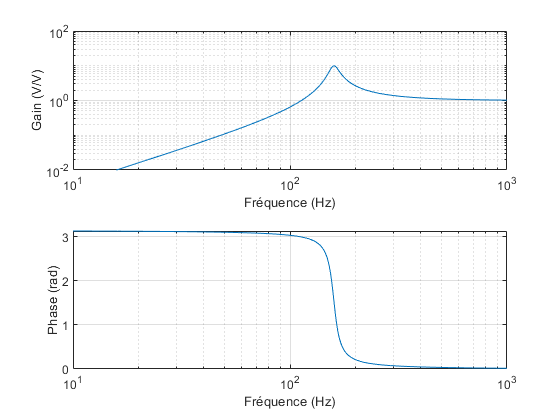

R=1e3;C=10e-6;L=0.1;
f=logspace(1,3,1000);
w=2*pi*f;
figure
subplot(2,1,1)
loglog(f,abs(subs(H)))
xlabel('Fréquence (Hz)');ylabel('Gain (V/V)');grid;ylim([1e-2,100])
subplot(2,1,2)
semilogx(f,angle(subs(H)))
xlabel('Fréquence (Hz)');ylabel('Phase (rad)');grid

[Hmax id]=max(double(abs(subs(H))))

Hmax = 10.0116

id = 602

La fréquence de la résonnace est f(id)

f(id)

ans = 159.6626

On retrouve les valeur théoriques : $\omega_0=1/\sqrt{LC}=1000 \ \rm rd/s$ $\Longrightarrow f_0=159\ \rm Hz$


$$Q=\frac{R}{L\omega_0}=10$$


Hmax=Q